%% Setup
clear;
close all;


## Load Image

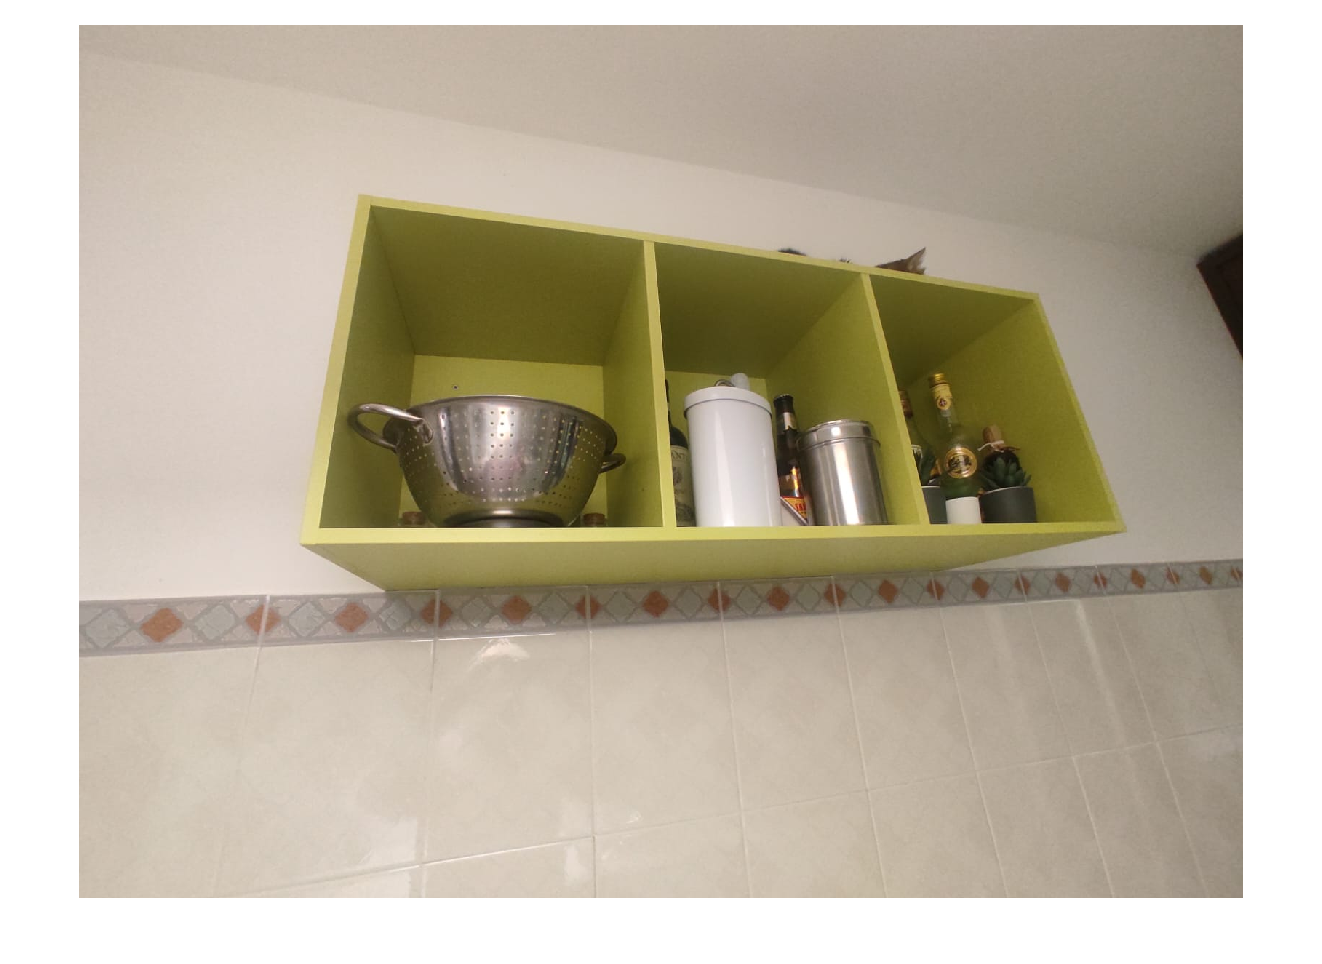

src = imread("../Assignment/Homework Image.jpg");
figure;
imshow(src);

## Convert to HSV

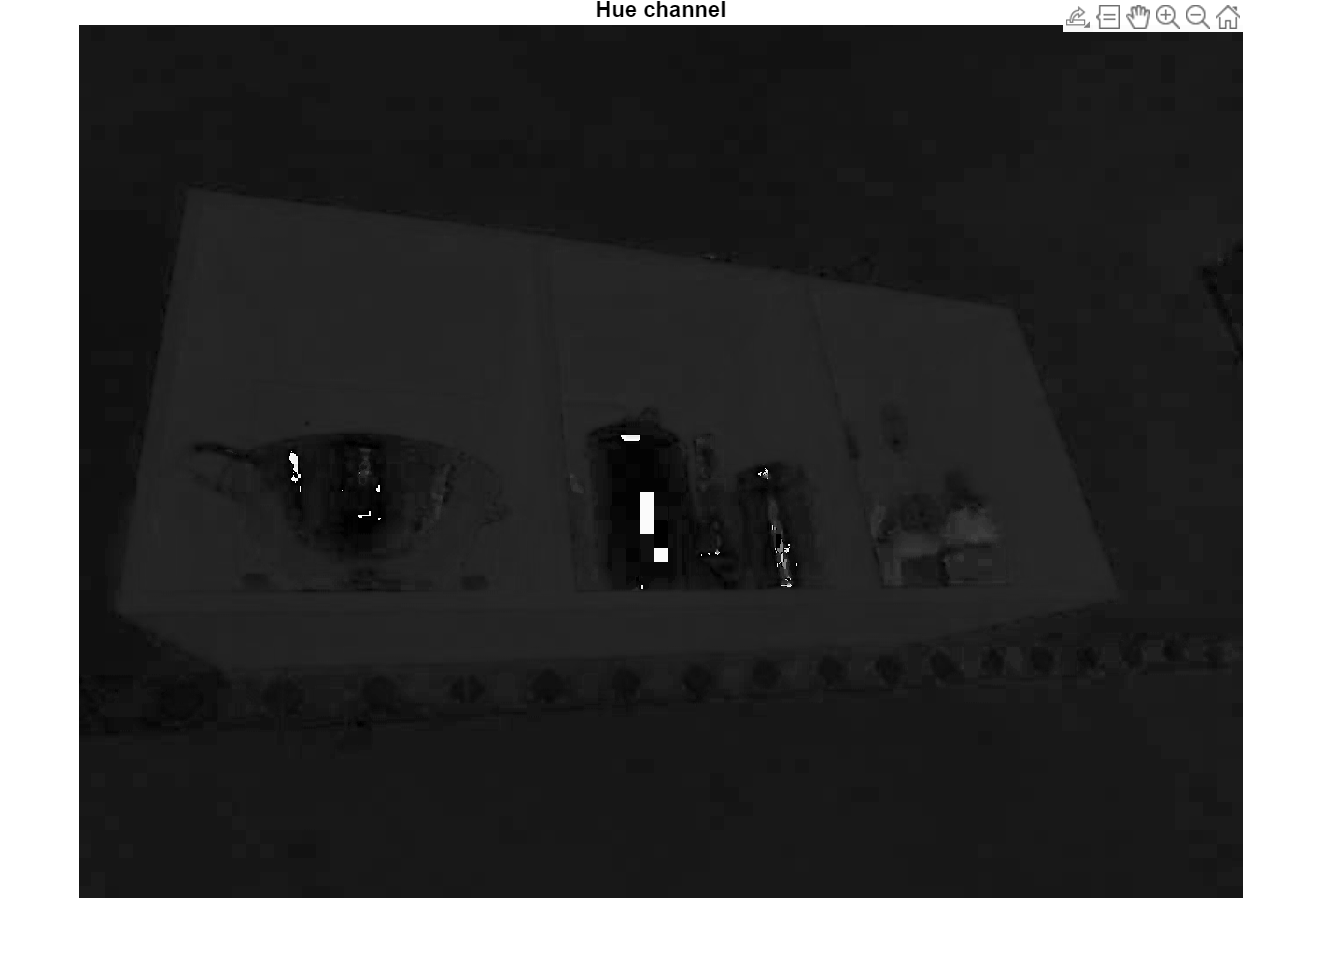

src_hsv = rgb2hsv(src);
hues = src_hsv(:, :, 1);
sats = src_hsv(:, :, 2);
figure;
imshow(hues), title("Hue channel");

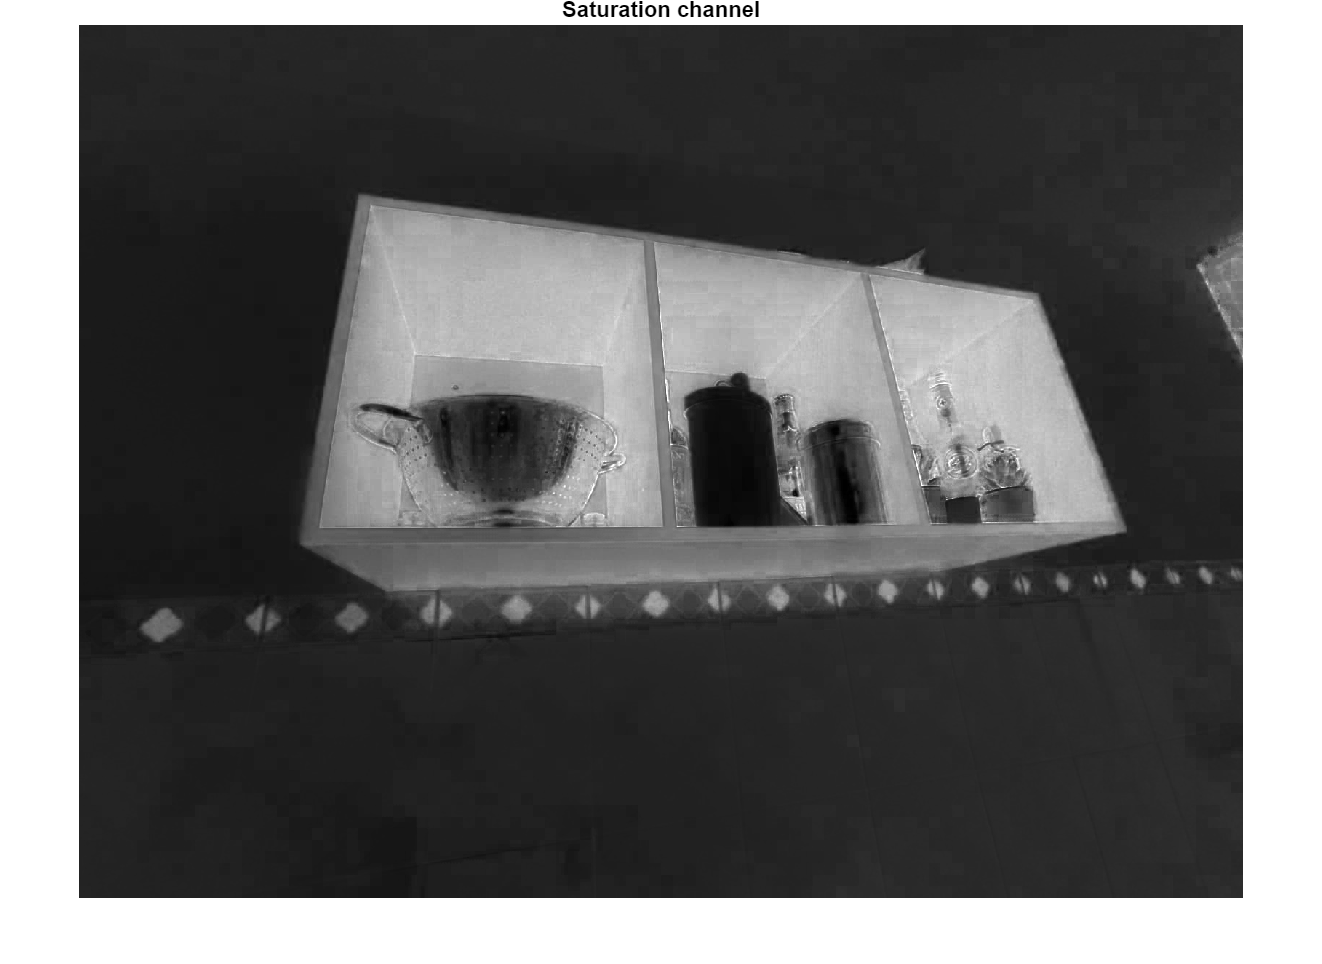

imshow(sats), title("Saturation channel");

## Create the binary mask

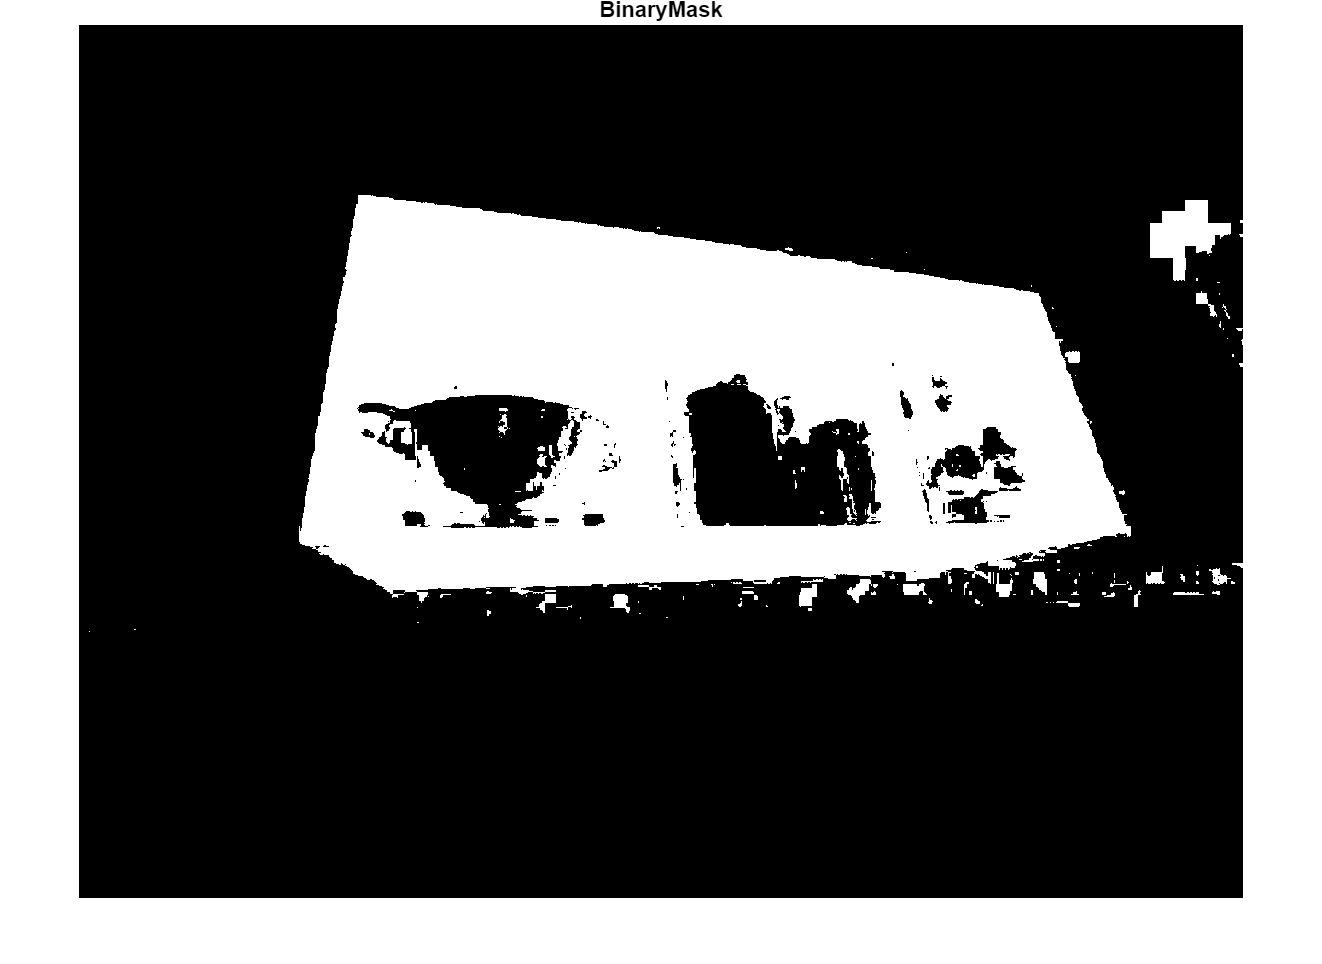

min_threshold =0.12;
max_threshold =0.2;
target = hues;
mask = (target >= min_threshold) & (target <= max_threshold);
imshow(mask), title("BinaryMask");

## Open the mask

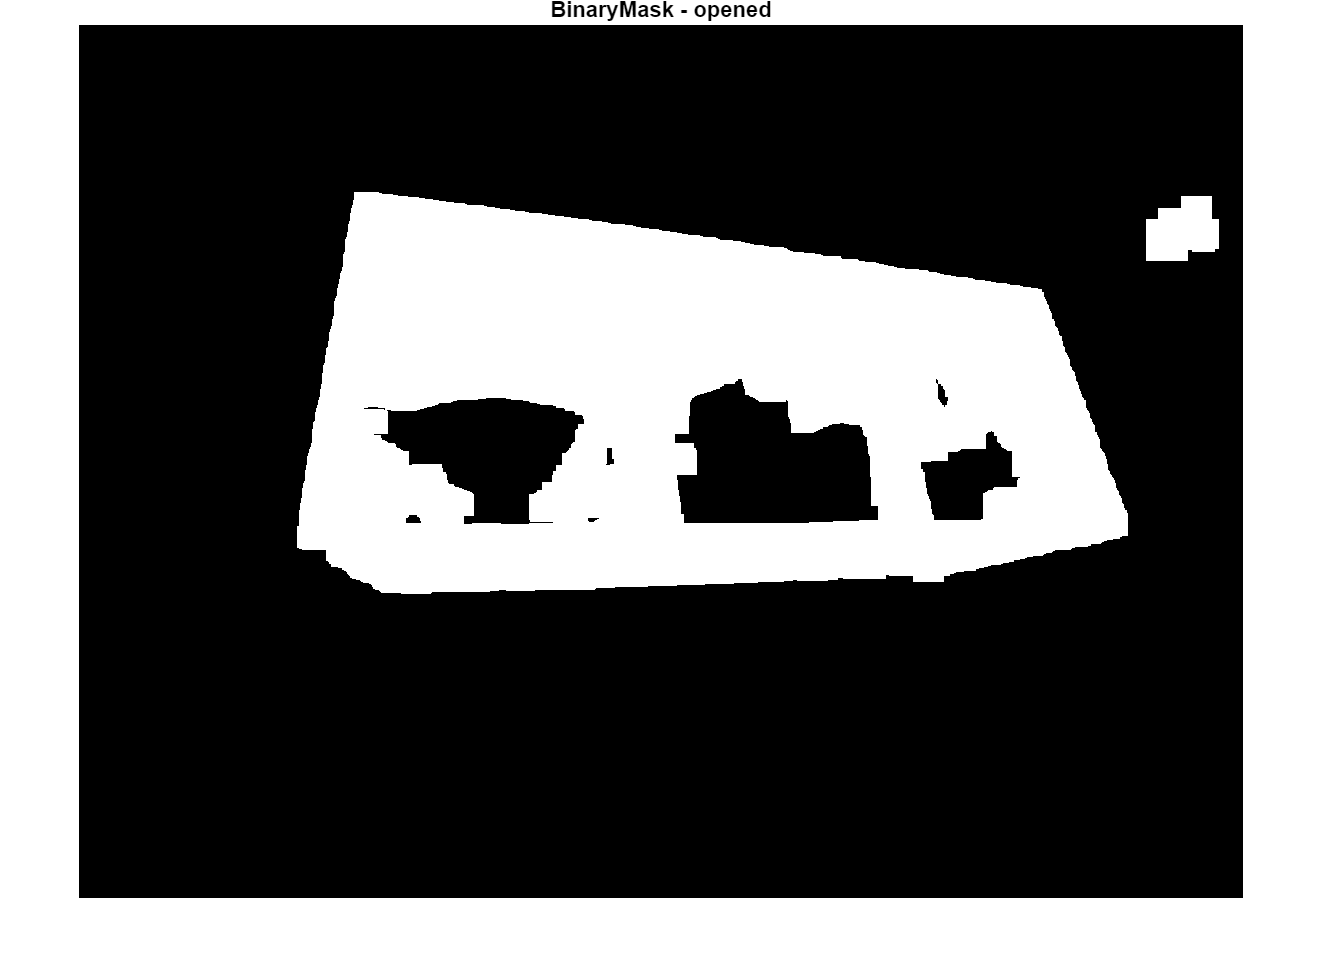

open_kernel_size = 21;
dialation_offset = 10;
opened_mask = imerode(mask, ones(open_kernel_size));
opened_mask = imdilate(opened_mask, ones(open_kernel_size + dialation_offset));
imshow(opened_mask), title("BinaryMask - opened");

## Smoothing

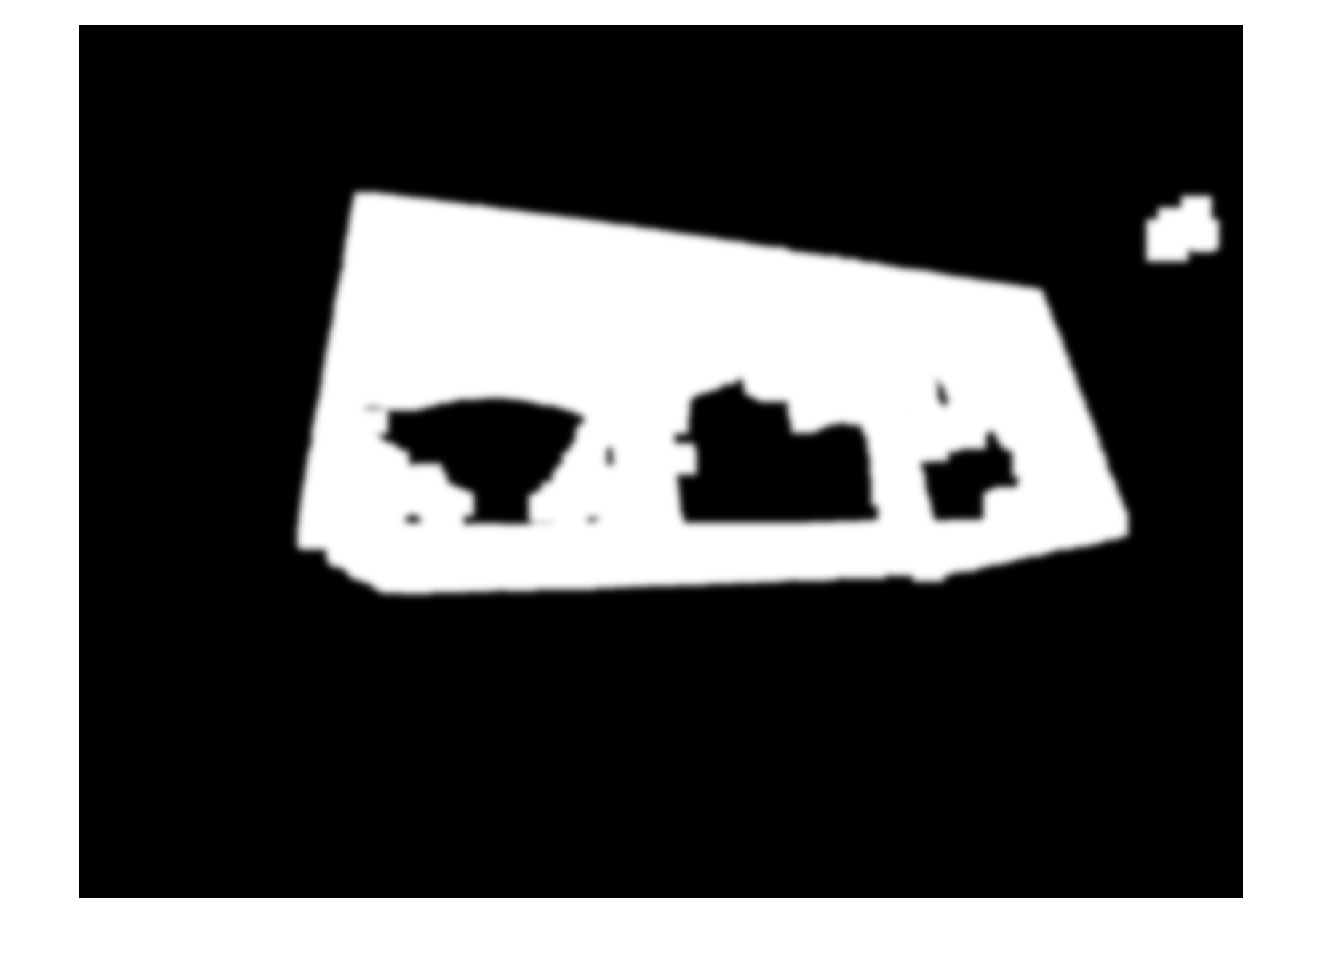

h_size = 51;
sigma_gauss = 5;
h = fspecial('gaussian' , h_size , sigma_gauss);

opened_mask_smoothed = conv2(opened_mask, h, 'same');

imshow(opened_mask_smoothed);

## Filtered image

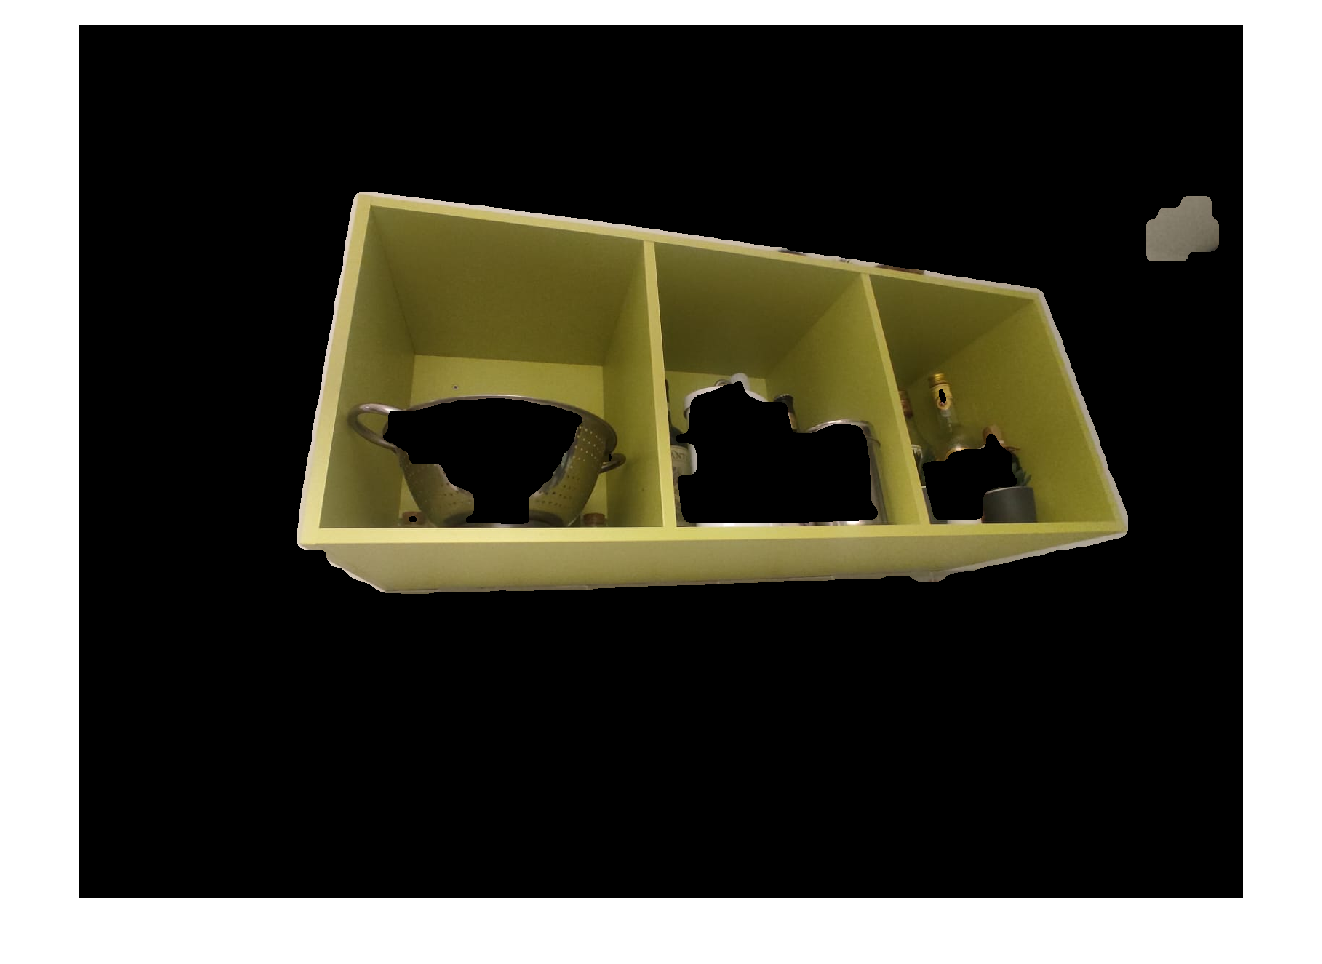

opened_mask_casted = cast(opened_mask_smoothed, class(src));
result = src;
result(:,:,1) = result(:,:,1).*opened_mask_casted;
result(:,:,2) = result(:,:,2).*opened_mask_casted;
result(:,:,3) = result(:,:,3).*opened_mask_casted;

imshow(result);